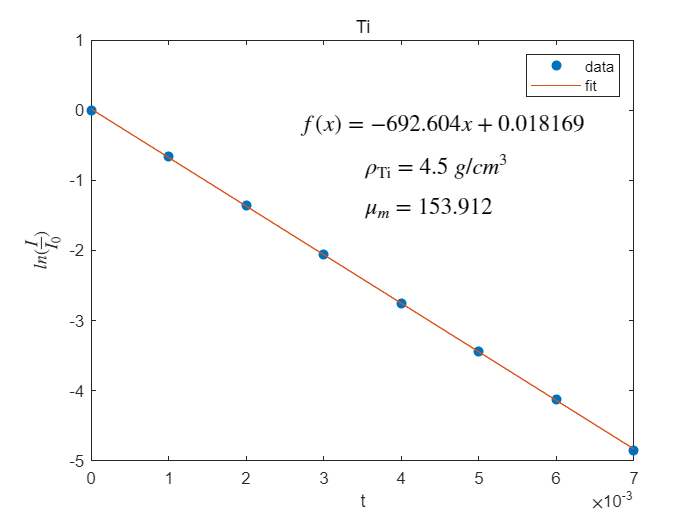

clear
Cr = [1396179/143.615 842691/134.078 454365/109.245 536477/196.422 151160/85.472 110546/95.23 72987/95.762 50516/101.089];
Cu = [232872/24.204 497222/58.515 287218/40.42 186734/30.261 153492/28.678 124089/26.853 89948/23.214 77629/21.821];
Fe = [1606343/165.379 1697512/227.699 114393/21.111 105980/27.534 191221/57.918 108151/43.75 115725/60.194 26778/18.104];
Ge = [330584/34.827 2079914/230.994 228203/27.786 227635/30.613 243540/35.21 143204/22.759 136587/22.912 256071/46.354];
Ti = [2120251/225.538 873198/180.693 597376/248.869 277456/229.337 212550/354.138 81414/269.367 26206/173.095 11620/157.787];
Zn = [217695/22.537 287959/34.184 206964/27.577 143675/21.471 221536/39.456 117350/21.934 137933/29.015 142502/33.604];
rho_Cr = 7.15;
rho_Cu = 8.96;
rho_Fe = 7.784;
rho_Ge = 5.323;
rho_Ti = 4.5;
rho_Zn = 7.13;
tit = {'Cr' 'Cu' 'Fe' 'Ge' 'Ti' 'Zn'};
data = [Cr;Cu;Fe;Ge;Ti;Zn];
rho = [rho_Cr rho_Cu rho_Fe rho_Ge rho_Ti rho_Zn];

n = 5;
M = data(n,:);
m = log(M/M(1));
N = 0:7;
N = N*1e-3;
f = fit(N',m','poly1');
draw(n,N,m,f,tit,rho)

function draw(n,N,m,f,tit,rho)

g = nexttile;
hold on
scatter(N,m,'filled')
plot(N,f(N))
box on
% title("$\frac{1}{2}$",'Interpreter','latex')
title(tit(n))
ylabel('$ln(\frac{I}{I_0})$','Interpreter','latex')
xlabel('t')
y1 = str2double(cell2mat(g.YTickLabel(1)));
y2 = str2double(cell2mat(g.YTickLabel(end)));
if f.p2 > 0
    pm = '+';
else
    pm = '-';
end
txt1 = ['$f(x)=' num2str(f.p1) 'x' pm num2str(abs(f.p2)) '$'];
txt2 = ['$\rho_{\mathrm{' cell2mat(tit(n)) '}}=' num2str(rho(n)) '\:g/cm^3$'];
txt3 = ['$\mu_m=' num2str(abs(f.p1/rho(n))) '$'];
text(max(N)*0.38,y1 + (y2-y1)*0.8,txt1,'Interpreter','latex','FontSize',14)
text(max(N)*0.5,y1 + (y2-y1)*0.7,txt2,'Interpreter','latex','FontSize',14)
text(max(N)*0.5,y1 + (y2-y1)*0.6,txt3,'Interpreter','latex','FontSize',14)
legend("data","fit")
end